# Data Preparation

clc
clear all
close all
rng(0)

A = [1  1  1  0  0  0  0  0  0;
     0  0  0  1  1  1  0  0  0;
     0  0  0  0  0  0  1  1  1;
    -1  0  0 -1  0  0 -1  0  0;
     0 -1  0  0 -1  0  0 -1  0;
     0  0 -1  0  0 -1  0  0 -1];
pinvA = pinv(A);
m = size(A, 2);
N = null(A, 'rational');
pinvN = pinv(N);

# Normalization parameters

To approximate the absolute limits on $i_{\varepsilon }$ and $i_B$, it is possible to sample points of randomly generated vectors of $i_s$ and knowing $i_{\textrm{xy}} =A\cdot i_s$, $i_B =\textrm{pinv}\left(A\right)\cdot i_{\textrm{xy}}$, $i_z =i_s -i_B$ and $i_{\varepsilon \;} =\textrm{pinv}\left(N\right)\cdot i_z$, statistical bounds can be found.

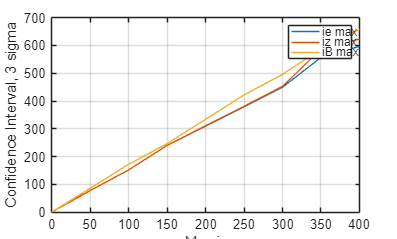

is_values = [0, 50, 100, 150, 250, 300, 350, 400];
n_experiments = length(is_values);
n_samples = 1000000;
ie_max_values = zeros(n_experiments, 1);
iz_max_values = zeros(n_experiments, 1);
iB_max_values = zeros(n_experiments, 1);

for idx = 1:n_experiments
    % Arcsine distribution for cluster currents
    % is = sin(2*pi*rand(9, n_samples))*is_values(idx);
    is = (2*rand(9, n_samples)-1)*is_values(idx);

    % Calculation of external currents
    ixy = A * is;
    % Calculation of basic currents
    iB = pinvA * ixy;
    % Calculation of circulating currents
    iz = is - iB;
    % Calculation of linear independent currents
    ie = pinvN * iz;

    % Confidence interval of basic currents
    % iB_max = std(iB(:))*3;
    iB_max = max(abs(iB(:)));
    % Confidence interval of circulating currents
    % iz_max = std(iz(:))*3;
    iz_max = max(abs((iz(:))));
    % Confidence interval of linearly independent currents
    % ie_max = std(ie(:))*3;
    ie_max = max(abs((ie(:))));

    ie_max_values(idx) = ie_max;
    iz_max_values(idx) = iz_max;
    iB_max_values(idx) = iB_max;
end
figure
plot(is_values, ie_max_values)
hold on
plot(is_values, iz_max_values)
plot(is_values, iB_max_values)
hold off
xlabel("Max is")
ylabel("Confidence Interval, 3 sigma")
legend('ie max', 'iz max', 'iB max')
grid on


idx = 5

idx = 5

x_bias = [ones(n_experiments, 1), is_values'];

beta = pinv(x_bias'*x_bias)*x_bias'*ie_max_values

beta =     2.5747
    1.5202


ie_max = beta'*[1; is_values(idx)]

ie_max = 382.6277

ie_max = ie_max_values(idx)

ie_max = 379.5059


beta = pinv(x_bias'*x_bias)*x_bias'*iz_max_values

beta =    -3.3579
    1.5881


iz_max = beta'*[1; is_values(idx)]

iz_max = 393.6622

iz_max = iz_max_values(idx)

iz_max = 381.0048


beta = pinv(x_bias'*x_bias)*x_bias'*iB_max_values

beta =     2.8270
    1.6531


iB_max = beta'*[1; is_values(idx)]

iB_max = 416.1112

iB_max = iB_max_values(idx)

iB_max = 421.8935


% *En el caso de las corrientes linealmente independientes, la maxima es
% aproximadamente ie_max=1.42*Is_max. Por esto se normalizará la salida de
% la red correspondiente al vector ie, por 1.5*Is_max.
% *Para Las corrientes circulantes, la máxima pareciera ser igual que las
% linealmente independiente.
% *Mientras que en el caso de las corrientes basicas, la maxima es
% aproximadamente iB_max=1.58*Is_max. Por esto se normalizará la entrada de
% la red correspondiente al vector iB, por 1.6*Is_max.

Input/outputs limits

Ax = 7000;
Ay = 5000;
[ix_max, iy_max, is_max, vo_max] = max_values(Ax, Ay)

ix_max = 200

iy_max = 280

is_max = 250

vo_max = 6000

Csm = 20e-3;
Nsm = 4;
C = Csm / Nsm

C = 0.0050

vc_mean_ref = (Ax+Ay)*1.5

vc_mean_ref = 18000


E = C/2 * vc_mean_ref^2 *1.1        % Capacitor energy

E = 8.9100e+05

VB = (Ax+Ay)                        % Branch voltages

VB = 12000

IB = 2*is_max                       % Basic currents

IB = 500

IE = 2*is_max                       % Linear independet currents

IE = 500

VO = vo_max                         % Common mode voltage

VO = 6000

IS = is_max                         % Cluster current

IS = 250

VXY = max([Ax, Ay]) * 1.1;          % External voltages
VX = Ax *1.1;
VY = Ay *1.1;
IXY = max([ix_max, iy_max]) *1.1;   % External currents
IX = ix_max *1.1;
IY = iy_max *1.1;

Xmax = [E*ones(9, 1); VX*ones(3, 1); VY*ones(3, 1); IX*ones(3, 1); IY*ones(3, 1)]

Xmax = 1.0e+05 *

    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    0.0770
    0.0770
    0.0770
    0.0550
    0.0550
    0.0550


Ymax = [IE*ones(4, 1); VO]

Ymax =          500
         500
         500
         500
        6000


# Load data from random data generator

load('ImitationLearning\TrainingData\Data\buffer.mat', 'buffer');
buffer = buffer';
Nbuffer_variables = size(buffer, 1)

Nbuffer_variables = 27

Nsamples = size(buffer, 2)

Nsamples = 10000


Ninputs = 21

Ninputs = 21

Noutputs = 5

Noutputs = 5


X = buffer(1:21, :); size(X)

ans =           21       10000


Y = buffer(22:26, :); size(Y)

ans =            5       10000


max(max(X(16:21, :)))

ans = 279.9842

# Preprocessing

Input/output sizes (MUST FIT WITH THE BUFFER SIZE)

[Ninputs, Nsamples] = size(X)

Ninputs = 21

Nsamples = 10000

[Noutputs, Nsamples] = size(Y)

Noutputs = 5

Nsamples = 10000

Normalization

X = X ./ Xmax;
Y = Y ./ Ymax;

Delete measurements with output data outside [-1, 1]

inside_range_index = sum(abs(Y)>1) == 0;
Nsamples = sum(inside_range_index)

Nsamples = 10000

X = X(:, inside_range_index);
Y = Y(:, inside_range_index);

Transform to dlarray

dlX = dlarray(X, 'CB');
dlY = dlarray(Y, 'CB');

Training/validation split

cv = cvpartition(Nsamples, 'HoldOut', 0.2);
idx_tr = training(cv);
idx_val = test(cv);

X_tr = X(:, idx_tr);
Y_tr = Y(:, idx_tr);
X_val = X(:, idx_val);
Y_val = Y(:, idx_val);

dlX_tr = dlX(:, idx_tr);
dlY_tr = dlY(:, idx_tr);
dlX_val = dlX(:, idx_val);
dlY_val = dlY(:, idx_val);

# Exploratory data analysis

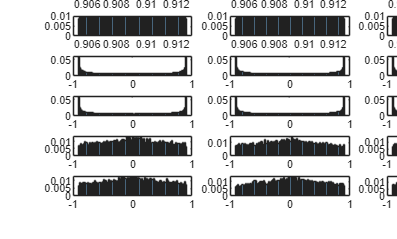

n_cols = 3;

figure
for idx = 1:Ninputs
    subplot(ceil(Ninputs / n_cols), n_cols, idx);
    if or(min(X(idx, :))<-1, max(X(idx, :))>1)
        histogram(X(idx, :), 100, 'Normalization', 'probability', 'FaceColor', 'red', 'EdgeColor', 'red');
    else
        histogram(X(idx, :), 100, 'Normalization', 'probability');
    end
    % title(['X', num2str(idx)]);
    % ylabel('Freq');
end
sgtitle('Input data distributions (X)')

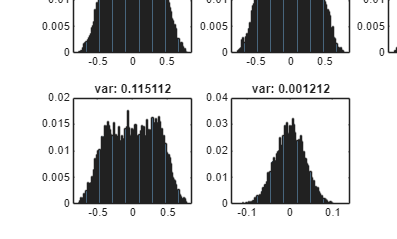


figure
for idx = 1:Noutputs
    subplot(ceil(Noutputs / n_cols), n_cols, idx)
    if or(min(Y(idx, :))<-1, max(Y(idx, :))>1)
        histogram(Y(idx, :), 100, 'Normalization', 'probability', 'FaceColor', 'red', 'EdgeColor', 'red')
    else
        histogram(Y(idx, :), 100, 'Normalization', 'probability')
    end
    title(sprintf('var: %f', var(Y(idx, :))))
end
sgtitle('Output data distributions (Y)')

# Sequential data

% Nwindow = 10;
% 
% Nseq = Nsamples - Nwindow + 1;
% 
% Xseq = cell(Nseq, 1);
% Yseq = cell(Nseq, 1);
% 
% for i = 1:Nseq
%     Xseq{i} = X(:, i:(i + Nwindow - 1));
%     Yseq{i} = Y(:, i + Nwindow - 1);
% end
% 
% Xmat = zeros(Ninputs, Nwindow, Nseq);
% Ymat = zeros(Noutputs, Nseq);
% 
% for i = 1:Nseq
%     Xmat(:, :, i) = Xseq{i};
%     Ymat(:, i) = Yseq{i};
% end
% 
% dlXseq = dlarray(Xmat, 'CTB');
% dlYseq = dlarray(Ymat, 'CB');

Train/validation split

% cv = cvpartition(size(dlYseq, 2), 'HoldOut', 0.2);
% 
% idx_tr = training(cv);
% idx_val = test(cv);
% 
% dlXseq_tr = dlXseq(:, idx_tr, :);
% dlYseq_tr = dlYseq(:, idx_tr);
% dlXseq_val = dlXseq(:, idx_val, :);
% dlYseq_val = dlYseq(:, idx_val);

# Dimensionality reduction for state space visualization

## PCA

Input

% [coeff, score, latent] = pca(X');
% 
% figure
% subplot(1, 2 ,1)
% scatter(score(:, 1), score(:, 2), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('2D');
% xlabel('pca_1');
% ylabel('pca_2');
% 
% subplot(1, 2, 2)
% scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('3D');
% xlabel('pca_1');
% ylabel('pca_2');
% zlabel('pca_3');
% 
% sgtitle('PCA X')

Output

% [coeff, score, latent] = pca(Y');
% 
% figure
% subplot(1, 2, 1)
% scatter(score(:, 1), score(:, 2), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('2D');
% xlabel('pca_1');
% ylabel('pca_2');
% 
% subplot(1, 2, 2)
% scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('3D');
% xlabel('pca_1');
% ylabel('pca_2');
% zlabel('pca_3');
% 
% sgtitle('PCA Y')

## Clustering

% n_clusters = 5; % Número de clusters
% epsilon = 0.1;  % Radio máximo para DBSCAN
% minPts = 5;     % Mínimo número de puntos para DBSCAN
% 
% % K-means
% [idx_kmeans, C_kmeans] = kmeans(Y', n_clusters, 'Replicates', 10);
% 
% % DBSCAN
% idx_dbscan = dbscan(Y', epsilon, minPts);
% 
% % GMM
% gmm = fitgmdist(Y', n_clusters, 'RegularizationValue', 1e-5);
% idx_gmm = cluster(gmm, Y');
% 
% % PCA
% num_dims = 3;
% [coeff, score, latent] = pca(Y');
% X_reduced = score(:, 1:num_dims);
% 
% figure
% 
% % K-means
% subplot(1, 3, 1)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_kmeans, 'filled');
% title('K-means'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% % DBSCAN
% subplot(1, 3, 2)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_dbscan, 'filled');
% title('DBSCAN'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% % GMM
% subplot(1, 3, 3)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_gmm, 'filled');
% title('GMM'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% sgtitle('Clustering in Original Space');

## UMAP

% pyenv('Version', '3.12', 'ExecutionMode', 'OutOfProcess')
% system('pip install umap-learn')

2D

% code =  [
%           "import umap"
%           "import numpy as np"
%           "reducer = umap.UMAP(n_neighbors=15, min_dist=0.001, n_components=2)"
%           "Xumap = reducer.fit_transform(np.transpose(X))"
%         ];
% 
% code = strjoin(code, newline);
% 
% Xumap = double(pyrun(code, 'Xumap', X=X));
% Yumap = double(pyrun(code, 'Xumap', X=Y));
% 
% figure;
% subplot(1, 2, 1);
% scatter(Xumap(:, 1), Xumap(:, 2), 1, 'filled');
% colormap(jet);
% title('UMAP X');
% xlabel('umap_1'); ylabel('umap_2'); grid on;
% 
% subplot(1, 2, 2);
% scatter(Yumap(:, 1), Yumap(:, 2), 1, 'filled');
% colormap(jet);
% title('UMAP Y');
% xlabel('umap_1'); ylabel('umap_2'); grid on;

3D

% code =  [
%           "import umap"
%           "import numpy as np"
%           "reducer = umap.UMAP(n_neighbors=15, min_dist=0.001, n_components=3)"
%           "Xumap = reducer.fit_transform(np.transpose(X))"
%         ];
% 
% code = strjoin(code, newline);
% 
% Xumap = double(pyrun(code, 'Xumap', X=X));
% Yumap = double(pyrun(code, 'Xumap', X=Y));
% 
% figure;
% subplot(1, 2, 1);
% scatter3(Xumap(:, 1), Xumap(:, 2), Xumap(:, 3), 1, 'filled');
% colormap(jet);
% title('UMAP X');
% xlabel('umap_1'); ylabel('umap_2'); zlabel('umap_3'); grid on;
% 
% subplot(1, 2, 2);
% scatter3(Yumap(:, 1), Yumap(:, 2), Yumap(:, 3), 1, 'filled');
% colormap(jet);
% title('UMAP Y');
% xlabel('umap_1'); ylabel('umap_2'); zlabel('umap_3'); grid on;